# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF1_2_Data_Analysys

## *Fetching and Visualizing Yahoo Finance Data*

This activity introduces the use of MATLAB to retrieve and analyze financial data directly from online sources (Yahoo Finance in this example).

You will learn how to:

- Download stock and index data from Yahoo Finance

- Plot stock prices over time

- Compute simple returns from prices

- Compare the dynamics of multiple stocks

- Export cleaned datasets for further analysis

At the end of this file, you will also find the function `fetchYahooFinanceData`, which is required to download the data. This function is embedded directly in the script so you can run everything without needing external files.

**Step 1 – Single Stock**

In this step, you will:

- Select a single ticker (e.g., SPY, the S&P 500 ETF)

- Download its historical prices from Yahoo Finance

- Plot the price series over time

- Compute and visualize the daily returns

% Define parameters
symbol = 'SPY';                     % Stock symbol for Apple Inc.
startDate = '01-Jan-2025';           % Start date
endDate = '24-Sep-2025';             % End date
interval = '1d';                     % Data interval ('1d', '1wk', '1mo')
fields = {'close'}; %{'open', 'high', 'low', 'close', 'volume'};  % Fields to retrieve

% Fetch data
stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields);

% Display the first 10 rows
disp(stockData(1:10, :));

            Date            Close 
    ____________________    ______

    02-Jan-2025 14:30:00    243.85
    03-Jan-2025 14:30:00    243.36
    06-Jan-2025 14:30:00       245
    07-Jan-2025 14:30:00    242.21
    08-Jan-2025 14:30:00     242.7
    10-Jan-2025 14:30:00    236.85
    13-Jan-2025 14:30:00     234.4
    14-Jan-2025 14:30:00    233.28
    15-Jan-2025 14:30:00    237.87
    16-Jan-2025 14:30:00    228.26



In the next section, prices are plotted next to the corresponding returns






subplot(1,2,1)
plot(stockData.Date,stockData.Close)
datetick('x','mmm yyyy')
title('SPY (S&P 500 ETF) – Prices')
subplot(1,2,2)
returns=price2ret(stockData.Close)

plot(stockData.Date(2:end),returns)
datetick('x','mmm yyyy')
title('SPY (S&P 500 ETF) – Returns')

**Step 2 – Multiple Stocks**

In this step, you will:

- Select a small, diversified universe of tickers across sectors

- Download and align their historical closing prices

- Handle missing data by interpolation

- Plot price series and normalized prices (base = 100)

- Export the combined dataset for further analysis

**Key Features:**

- **Data Fetching:**

- Retrieves closing prices for a list of stock indices using a custom function (`fetchYahooFinanceData`).

- User specifies parameters such as the date range, data interval (e.g., daily), and desired fields (e.g., 'close').

**2. Date Standardization:**

- Removes time components from dates to focus solely on the calendar day.

- Sets all dates to midnight (start of the day) to ensure consistent alignment across different time zones and indices.

**3. Date Vector Options:**

- **Option 1: Comprehensive Date Vector**

- Uses all unique dates from all indices to create a comprehensive date vector.

- Ensures inclusion of every trading day from any index.

- May introduce more interpolated values due to varying trading days among indices.

- **Option 2: Reference Index Date Vector**

- Uses the date vector from a specific reference index (e.g., the first index in the list).

- Aligns all indices to the trading days of the selected index.

- May exclude dates unique to other indices, potentially reducing interpolation.

(In the code we use Comprehensive Date Vector, i.e. Option1)

To illustrate financial data analysis, we will use a small set of **large, liquid stocks**.

They are widely traded, well known, and represent different sectors.

This allows us to demonstrate the principle of **diversification**: when sectors move differently, portfolio risk is reduced.

**Tech**

- Apple (`AAPL`)

- Microsoft (`MSFT`)

- Nvidia (`NVDA`)

- Alphabet Class A (`GOOGL`)

**Finance**

- JPMorgan Chase (`JPM`)

- Goldman Sachs (`GS`)

- HSBC Holdings (`HSBC`)

**Consumer**

- Coca-Cola (`KO`)

- Procter & Gamble (`PG`)

**Energy**

- ExxonMobil (`XOM`)

- Shell (`SHEL`)

% Script to fetch and combine closing prices for multiple stock indices with interpolation

% List of stock index symbols
symbols = {'AAPL','MSFT','NVDA','GOOGL','JPM','GS','HSBC','KO','PG','XOM','SHEL'};


% Define the date range and parameters
startDate = '01-Jan-2025';
endDate = '01-Sep-2025';
interval = '1d';        % Daily data
fields = {'close'};     % Only closing prices

% Number of symbols
numSymbols = length(symbols);

% Cell arrays to store data
stockDataCell = cell(numSymbols, 1);
timetablesCell = cell(numSymbols, 1);

% Fetch data for each symbol and convert to timetable
for k = 1:numSymbols
    symbol = symbols{k};
    fprintf('Fetching data for %s...\n', symbol);
    
    try
        % Fetch data using the custom function
        stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields);
        
        % Remove time component and set dates to midnight
        stockData.Date = dateshift(stockData.Date, 'start', 'day');
        
        % Rename the 'Close' column to the symbol name
        varName = matlab.lang.makeValidName(symbol);
        stockData.Properties.VariableNames{'Close'} = varName;
        
        % Convert to timetable
        tt = table2timetable(stockData, 'RowTimes', 'Date');
        
        % Store the timetable
        timetablesCell{k} = tt(:, varName);  % Only include the price column
    catch ME
        warning('Failed to fetch data for %s: %s', symbol, ME.message);
        timetablesCell{k} = timetable();  % Empty timetable
    end
end

Fetching data for AAPL...
Fetching data for MSFT...
Fetching data for NVDA...
Fetching data for GOOGL...
Fetching data for JPM...
Fetching data for GS...
Fetching data for HSBC...
Fetching data for KO...
Fetching data for PG...
Fetching data for XOM...
Fetching data for SHEL...



% Remove empty timetables
nonEmpty = ~cellfun(@isempty, timetablesCell);
timetablesCell = timetablesCell(nonEmpty);
symbols = symbols(nonEmpty);

% Collect all unique dates from all indices
allDates = [];
for k = 1:length(timetablesCell)
    allDates = [allDates; timetablesCell{k}.Date];
end

% Get unique sorted dates
commonDates = unique(allDates);

% Sort dates
commonDates = sort(commonDates);

% Resample all timetables to the common dates with interpolation
for k = 1:length(timetablesCell)
    % Synchronize to common dates with linear interpolation
    timetablesCell{k} = retime(timetablesCell{k}, commonDates, 'linear');
end

% Combine all timetables into one
combinedTimetable = timetablesCell{1};
for k = 2:length(timetablesCell)
    combinedTimetable = synchronize(combinedTimetable, timetablesCell{k}, 'union', 'linear');
end

% Convert timetable to table
combinedData = timetable2table(combinedTimetable);

% Rename the time variable to 'Date'
combinedData.Properties.VariableNames{1} = 'Date';

% Display the first few rows
disp('Combined Data (First 10 Rows):');

Combined Data (First 10 Rows):


disp(head(combinedData, 10));

       Date         AAPL      MSFT      NVDA     GOOGL      JPM        GS      HSBC      KO        PG       XOM      SHEL 
    ___________    ______    ______    ______    ______    ______    ______    _____    _____    ______    ______    _____

    02-Jan-2025    243.85    418.58    138.31    189.43       240    574.97    48.68    61.84    165.98    107.31     63.1
    03-Jan-2025    243.36    423.35    144.47    191.79    243.28    580.13    49.07    61.75    165.13    107.86    64.52
    06-Jan-2025       245    427.85    149.43    196.87    240.85    583.39    49.27    60.81     1


% Write the combined data to an Excel file
writetable(combinedData, 'Data.xlsx');
fprintf('Data with interpolated missing values has been written to StockIndicesData_Interpolated.xlsx\n');

Data with interpolated missing values has been written to StockIndicesData_Interpolated.xlsx


**Visual Comparison through Normalization**

When stock prices differ greatly in scale (for example, $50 vs. $500), plotting them together can be misleading — higher-priced stocks dominate the figure.

To make visual comparison meaningful, we rescale each price series so that they share a common reference.

One common choice is to **normalize each series by its initial value** so that all start at 100. This highlights *relative performance* over time rather than absolute price levels.

Alternatively, you can normalize each series by its **Euclidean norm** (using `P ./ vecnorm(P)`), which scales the data so that all series have comparable magnitudes — useful when focusing on overall patterns or correlations rather than percentage growth.

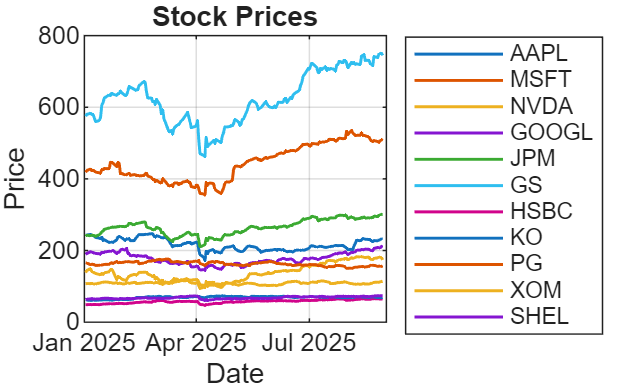


% TT: timetable with RowTimes (datetime) and 12 variables (tickers)
TT=combinedTimetable;
TT = rmmissing(TT);                  % drop rows with any NaN (optional)
[~,ix] = unique(TT.Properties.RowTimes); 

TT = TT(ix,:);                       % ensure unique, sorted times

figure
plot(TT.Properties.RowTimes, TT{:, :}, 'LineWidth', 1)
grid on
xlabel('Date'); ylabel('Price')
title('Stock Prices')
legend(TT.Properties.VariableNames, 'Interpreter','none', 'Location','bestoutside')

% Tidy date format
ax = gca;
ax.XAxis.TickLabelFormat = 'MMM yyyy';   % e.g., Jan 2024

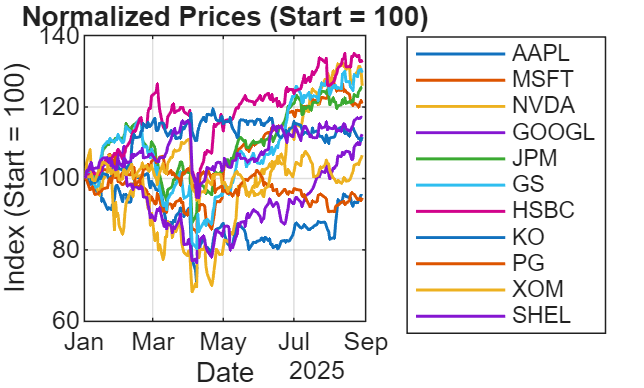

% Normalize by first observation (base = 100)
P = TT{:, :};
Pnorm = P ./ P(1,:) * 100;

figure
plot(TT.Properties.RowTimes, Pnorm, 'LineWidth', 1)
grid on
xlabel('Date'); ylabel('Index (Start = 100)')
title('Normalized Prices (Start = 100)')
legend(TT.Properties.VariableNames, 'Interpreter','none', 'Location','bestoutside')

gca.XAxis.TickLabelFormat = 'MMM yyyy';



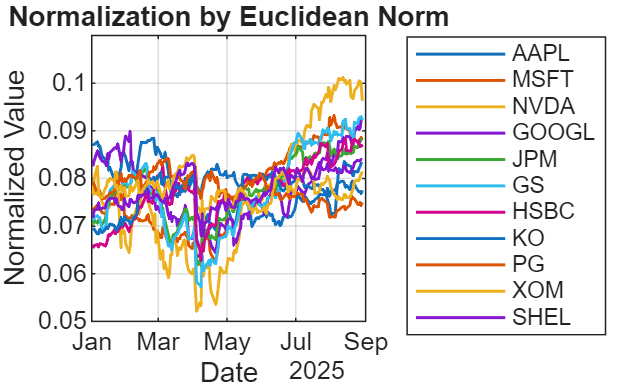

% Normalize by Euclidean norm (pattern comparison)
Pnorm2 = P ./ vecnorm(P);

figure
plot(TT.Properties.RowTimes, Pnorm2, 'LineWidth', 1)
grid on
xlabel('Date'); ylabel('Normalized Value')
title('Normalization by Euclidean Norm')
legend(TT.Properties.VariableNames, 'Interpreter','none', 'Location','bestoutside')

gca.XAxis.TickLabelFormat = 'MMM yyyy';



- The **base-100** version is better for *economic interpretation* (percentage growth).

- The **Euclidean norm** version is better for *statistical comparison* (pattern and co-movement).

### FUNTION: fetchYahooFinanceData()

The `fetchYahooFinanceData` function is a custom MATLAB utility designed to programmatically retrieve historical financial data from Yahoo Finance. It allows users to specify a stock or index symbol, date range, data interval (such as daily or monthly), and the specific data fields they wish to obtain (like 'open', 'close', 'high', 'low', or 'volume'). The function returns the data in a structured MATLAB table, facilitating easy manipulation and analysis within the MATLAB environment.

Under the hood, the function scrapes data from Yahoo Finance by sending HTTP requests to Yahoo's financial data endpoints and retrieving responses in JSON format. Since Yahoo Finance has made several changes to its APIs over time—including discontinuing some public endpoints—the function incorporates workarounds to handle these changes. These workarounds may involve using updated API endpoints, managing session cookies, handling crumb tokens for authentication, or parsing the data differently to accommodate the new data structures introduced by Yahoo.

function stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
% fetchYahooFinanceData Fetches historical stock data from Yahoo Finance.
%
%   stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
%
%   Parameters:
%       symbol     - Stock symbol as a string (e.g., 'AAPL').
%       startDate  - Start date as a string or datetime ('dd-mmm-yyyy' format).
%       endDate    - End date as a string or datetime ('dd-mmm-yyyy' format).
%       interval   - Data interval: '1d' (daily), '1wk' (weekly), '1mo' (monthly).
%       fields     - Cell array of strings -i.e.curly brackets needed to
%       enter input, specifying data fields to retrieve, one or more
%                    Valid fields: 'open', 'close', 'high', 'low',
%                    'volume'. e.g.{'open', 'high', 'low', 'close', 'volume'}, 
%
%   Returns:
%       stockData  - Table containing the date and requested data fields.

    % Validate inputs
    if nargin < 5
        error('All five arguments (symbol, startDate, endDate, interval, fields) are required.');
    end

    % Convert dates to datetime if necessary
    if ischar(startDate) || isstring(startDate)
        startDate = datetime(startDate, 'InputFormat', 'dd-MMM-yyyy');
    end
    if ischar(endDate) || isstring(endDate)
        endDate = datetime(endDate, 'InputFormat', 'dd-MMM-yyyy');
    end

    % Validate interval
    validIntervals = {'1d', '1wk', '1mo'};
    if ~ismember(interval, validIntervals)
        error('Invalid interval. Choose from ''1d'', ''1wk'', or ''1mo''.');
    end

    % Convert dates to UNIX timestamps
    startNum = posixtime(datetime(startDate));
    endNum = posixtime(datetime(endDate));

    % Construct the URL
    url = ['https://query1.finance.yahoo.com/v8/finance/chart/' symbol ...
           '?period1=' num2str(floor(startNum)) '&period2=' num2str(floor(endNum)) '&interval=' interval];

    % Set web options with a user-agent header to mimic a browser
    options = weboptions('ContentType', 'json', 'UserAgent', 'Mozilla/5.0');

    % Fetch data
    try
        data = webread(url, options);
    catch ME
        error('Failed to retrieve data: %s', ME.message);
    end

    % Check for errors in response
    if isempty(data.chart.result) || ~isempty(data.chart.error)
        error('Failed to retrieve data. Please check the stock symbol and date range.');
    end

    % Extract the result
    result = data.chart.result;
    if iscell(result)
        result = result{1};
    elseif isstruct(result) && numel(result) > 1
        result = result(1);
    end

    % Extract timestamps
    if isfield(result, 'timestamp')
        timestamps = result.timestamp;
    else
        error('No timestamp data available.');
    end

    % Convert timestamps to datetime
    dates = datetime(timestamps, 'ConvertFrom', 'posixtime', 'TimeZone', 'UTC');

    % Access indicators
    if isfield(result, 'indicators') && isfield(result.indicators, 'quote')
        quote = result.indicators.quote;
        if iscell(quote)
            quote = quote{1};
        elseif isstruct(quote) && numel(quote) > 1
            quote = quote(1);
        end
    else
        error('No quote data available.');
    end

    % Initialize table with dates
    stockData = table(dates, 'VariableNames', {'Date'});

    % Ensure fields are in lowercase
    fields = lower(fields);

    % Valid fields in the data
    validFields = fieldnames(quote);

    % For each requested field, extract the data
    for i = 1:length(fields)
        field = fields{i};
        if ismember(field, validFields)
            fieldData = quote.(field);
            fieldData = fieldData(:);  % Ensure column vector
            % Handle missing data
            if length(fieldData) < length(dates)
                fieldData(end+1:length(dates)) = NaN;
            elseif length(fieldData) > length(dates)
                fieldData = fieldData(1:length(dates));
            end
            % Append to table with capitalized field name
            stockData.(capitalizeFirstLetter(field)) = fieldData;
        else
            warning('Field "%s" is not available in the data.', field);
            % Fill with NaNs if field is missing
            stockData.(capitalizeFirstLetter(field)) = NaN(height(stockData), 1);
        end
    end

    % Remove rows where all data fields are NaN
    dataFields = stockData.Properties.VariableNames(2:end);
    validRows = any(~isnan(stockData{:, dataFields}), 2);
    stockData = stockData(validRows, :);

    % Reset the datetime to remove time zone information
    stockData.Date.TimeZone = '';

end

function outStr = capitalizeFirstLetter(inStr)
% Helper function to capitalize the first letter of a string
    outStr = lower(inStr);
    if ~isempty(outStr)
        outStr(1) = upper(outStr(1));
    end
end
